## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 10 - Three Point Rotational Springs**

#### **10.1 Potential of a three-point rotational springs**

Three-point rotational springs are found in many engineered systems like mechanical watches, self closing doors, clothespins, etc. In addition, this rotational spring can also be used to measure the stiffness of a folding crease joint (see figure) or be used to represent the bending stiffness of complian mechanisms based on the pseudo-rigid-body model. We will derive this rotational spring element in 3D space to keep it general. A rotational spring like this is defined using three nodal coordinates:

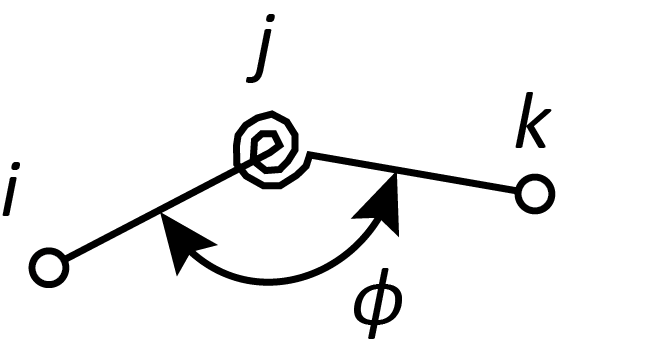

The way we can formulate a potential for this spring is to first find the angle $\phi \;$and then formulate potential of the spring from the angle. What we can do to find the rotational spring's angle is to use the arc cosine function. 

% Find the rotational spring angle from nodal coordinates
function theta = Find_Angle(xi,xj,xk)
    vector1=xi-xj;
    vector2=xk-xj;
    theta=acos(dot(vector1,vector2)/norm(vector1)/norm(vector2));
end

We can test out how this works:

% Define three nodes
xi=[1 0 0];
xj=[0 0 0];
xk=[0 0 1];
theta=Find_Angle(xi,xj,xk);
theta

theta = 1.5708

Looking good! The angle is indeed 90 degree (1.57 rad). With this equation to calculate the rotational angle, we will be able to construct the potential based on the theta angle. For a linear elastic spring element, we can have:


$$U\left(\mathit{\mathbf{x}}\right)=\frac{1}{2}{K\left(\phi \left(\mathit{\mathbf{x}}\right)-\phi_0 \right)}^2$$


where the term $K$ is the stiffness of the rotational spring, and the term $\phi_0 \;$is the rest angle of the rotational spring. In addition, we also notice that the entire potential is a function of the nodal coordinates of the related nodes. The total potential can be formulated as:

% Find the rotational spring potential from nodal coordinates
function potential = Find_Potential(xi,xj,xk,k,theta0)
    theta=Find_Angle(xi,xj,xk);
    potential=1/2*((theta-theta0)^2)*k;
end

#### **10.2 Central Difference**

Now that we have the potential calculated and coded. We will follow the exact process in Section 02 to calculate the internal forces and the stiffness matrix for the three node rotational spring function. Everything is the same except that we will now have a 9 by 1 force vector and a 9 by 9 stiffness matrix. 

Assuming that the three nodes are:


$${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} =\left\lbrack x_i ,y_i ,z_i \right\rbrack$$



$${\mathit{\mathbf{x}}}_j =\left\lbrack x_j ,y_j ,z_j \right\rbrack$$



$${\mathit{\mathbf{x}}}_k =\left\lbrack x_k ,y_k ,z_k \right\rbrack$$


The internal forces of the bar can be calculated as the Jacobian of the potential:


$${\mathit{\mathbf{F}}}_{\textrm{spr}} =\nabla_{\mathit{\mathbf{x}}} U_{\textrm{spr}}$$



$${\mathit{\mathbf{F}}}_{\textrm{bar}} =\left\lbrack \begin{array}{c}
F_{x_{i\;} } \\
F_{y_{i\;} } \\
F_{z_{i\;} } \\
F_{x_{j\;} } \\
F_{y_{j\;} } \\
F_{z_{j\;} } \\
F_{x_{k\;} } \\
F_{y_{k\;} } \\
F_{z_{k\;} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\partial U_{\textrm{spr}} }{\partial x_i }\\
\frac{\partial U_{\textrm{spr}} }{\partial y_i }\\
\frac{\partial U_{\textrm{spr}} }{\partial z_i }\\
\frac{\partial U_{\textrm{spr}} }{\partial x_j }\\
\frac{\partial U_{\textrm{spr}} }{\partial y_j }\\
\frac{\partial U_{\textrm{spr}} }{\partial z_j }\\
\frac{\partial U_{\textrm{spr}} }{\partial x_k }\\
\frac{\partial U_{\textrm{spr}} }{\partial y_k }\\
\frac{\partial U_{\textrm{spr}} }{\partial z_k }
\end{array}\right\rbrack$$


If you compare this vector with what we have in Section 02, you will see that the structure is exactly the same. Then, using the central difference method, we can calculate the values as the following, using the $x_{i\;}$and $y_i$ direction:


$$\frac{\partial U_{\textrm{spr}} }{\partial x_i }=\frac{U_{\textrm{spr}\;} \left(x_i +\delta \;,y_{i\;} ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} \right)-U_{\textrm{spr}\;} \left(x_i -\delta \;,y_{i\;} ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} \right)}{2\delta \;}\;$$



$$\frac{\partial U_{\textrm{spr}} }{\partial y_i }=\frac{U_{\textrm{spr}\;} \left(x_i \;,y_{i\;} +\delta ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} \right)-U_{\textrm{spr}\;} \left(x_i \;,y_{i\;} -\delta ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} ,x_k ,y_{k\;} ,z_{k\;} \right)}{2\delta \;}\;$$


We can repeat this for all nine entries in the Jacobian vector and obtain the internal force vector. This calculation can be done using a for loop as the following:

function F=Local_Spr_Force(xi,xj,xk,theta0,kspr,delta)
    F=zeros(9,1);
    % The local force vector is 6*1 vector
    for i=1:3
        x_forward=xi;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xi;
        x_backward(i)=x_backward(i)-delta;
        F(i)=(Find_Potential(x_forward,xj,xk,kspr,theta0)-...
            Find_Potential(x_backward,xj,xk,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % first node xi

        x_forward=xj;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xj;
        x_backward(i)=x_backward(i)-delta;
        F(3+i)=(Find_Potential(xi,x_forward,xk,kspr,theta0)-...
            Find_Potential(xi,x_backward,xk,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % second node xj

        x_forward=xk;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xk;
        x_backward(i)=x_backward(i)-delta;
        F(6+i)=(Find_Potential(xi,xj,x_forward,kspr,theta0)-...
            Find_Potential(xi,xj,x_backward,kspr,theta0))/2/delta;
        % calculate the central difference for the 
        % third node xk
    end
end

#### **10.3 Internal Force Vector Example**

Let's visualize the above code to get a better understanding of the behavior of the rotational spring. When plotting the results, we will skip the y-direction because we assume that the rotational hinge lives in the x-z plane. However, we still calcualte the forces in 3D. 

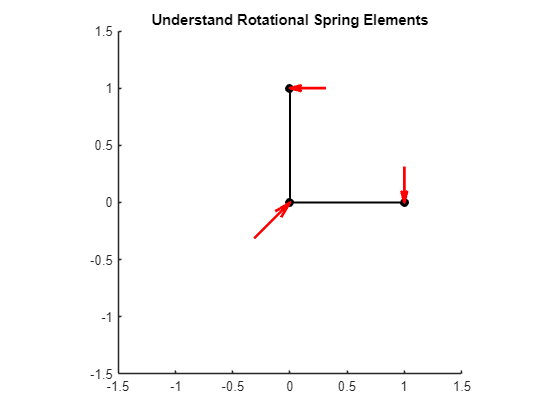

theta=0.5*pi; % The rotation angle
theta0=0.7*pi; % The stress free rotation angle

% The nodal coordinates of the rotational spring is 
% of the following values
xi=[1;0;0];
xj=[0;0;0];
xk=[cos(theta);0;sin(theta)];


kspr=1; % The rotational spring stiffness value
delta=10^-6; % Step length for the central difference method

% Solve for the forces of the rotational spring
% Here we can directly use the function we already created
sprForce=Local_Spr_Force(xi,xj,xk,theta0,kspr,delta);

% Plot the figgure
figure
hold on
title('Understand Rotational Spring Elements')
set(gca,'DataAspectRatio',[1 1 1])
axis([-1.5,1.5,-1.5,1.5,-1.5,1.5])
% This is the deformed bar location
plot([xi(1),xj(1)],[xi(3),xj(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)
plot([xj(1),xk(1)],[xj(3),xk(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)

% Next we plot the forces acting on the bar
% We can use the Quiver function to do this
scaleFactor=-0.5;
% This is the force at the i-th node
quiver(xi(1)-sprForce(1)*scaleFactor,...
    xi(3)-sprForce(3)*scaleFactor,...
    +sprForce(1)*scaleFactor,...
    +sprForce(3)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)
% This is the force at the j-th node
quiver(xj(1)-sprForce(4)*scaleFactor,...
    xj(3)-sprForce(6)*scaleFactor,...
    +sprForce(4)*scaleFactor,...
    +sprForce(6)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)
% This is the force at the k-th node
quiver(xk(1)-sprForce(7)*scaleFactor,...
    xk(3)-sprForce(9)*scaleFactor,...
    +sprForce(7)*scaleFactor,...
    +sprForce(9)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=2)

Now, play with the stress free angle and the nodal coordinates, we can see that the forces do create a moment to close or open the three node hinge when the current rotational angle is not the same as the stress free angle. This behavior is just like what we expect to happen. 

#### **10.4 Hessian Matrix and Stiffness**

For this three-node rotational spring elements, the stiffness matrix can also be solved using the Hessian matrix of the potential of the system. Here, the matrix will be 9 by 9. Let's start to write this in block and start getting used to taking derivatives about vectors.


$${\mathit{\mathbf{K}}}_{\textrm{spr}} =\Delta_{\mathit{\mathbf{x}}} U_{\textrm{spr}} =\left\lbrack \begin{array}{ccc}
\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{i\;} \partial {\mathit{\mathbf{x}}}_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{i\;} \partial {\mathit{\mathbf{x}}}_{k\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{\mathit{\mathbf{j}}\;} \partial {\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_j^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{j\;} \partial {\mathit{\mathbf{x}}}_{k\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{k\;} \partial {\mathit{\mathbf{x}}}_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{k\;} \partial {\mathit{\mathbf{x}}}_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_k^{2\;} }
\end{array}\right\rbrack$$


where each block is a 3 by 3 matrix. For example:


$$\frac{\partial^2 U_{\textrm{bar}} }{\partial {\mathit{\mathbf{x}}}_{i\;} \partial {\mathit{\mathbf{x}}}_{j\;} }=\left\lbrack \begin{array}{ccc}
\frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial x_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial y_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial z_{j\;} }
\end{array}\right\rbrack$$


Please note that bold represent vectors and each node is:

${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} =\left\lbrack x_{i\;} ,y_{i\;} ,z_{i\;} \right\rbrack$;

${\mathit{\mathbf{x}}}_j =\left\lbrack x_{j\;} ,y_{j\;} ,z_{j\;} \right\rbrack$;

${\mathit{\mathbf{x}}}_k =\left\lbrack x_k ,y_k ,z_{k\;} \right\rbrack$;

Then, following the same mathematical trsanformation we did in Section 02, every column in the stiffness matrix can be writen as derivative of a force vector. For example, the first column of this stiffness matrix is:


$$\left\lbrack \begin{array}{c}
\frac{\partial^2 U_{\textrm{spr}} }{\partial x_i^{2\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial y_{i\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial z_{i\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial x_{j\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial y_{j\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial z_{j\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial x_{k\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial y_{k\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{spr}} }{\partial z_{k\;} \partial x_{i\;} }
\end{array}\right\rbrack =\frac{\;\partial }{\;\partial \;x_{i\;} }\left\lbrack \begin{array}{c}
\frac{\partial U_{\textrm{spr}} }{\partial x_i }\\
\frac{\partial U_{\textrm{spr}} }{\partial y_i }\\
\ldotp \ldotp \ldotp \\
\ldotp \ldotp \ldotp \\
\frac{\partial U_{\textrm{spr}} }{\partial k}\\
\frac{\partial U_{\textrm{spr}} }{\partial k}
\end{array}\right\rbrack =\frac{\;\partial }{\;\partial \;x_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{spr}} \right)$$


Basically, this is to apply central difference about the $x_{i\;}$direction again to the force vector we previously computed. Then, applying the above notation to the full matrix will give us:


$${\mathit{\mathbf{K}}}_{\textrm{spr}} =\Delta_{\mathit{\mathbf{x}}} U_{\textrm{spr}} =\left\lbrack \begin{array}{cccccc}
\frac{\;\partial }{\;\partial \;x_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{spr}} \right) & \frac{\;\partial }{\;\partial \;y_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{spr}} \right) & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \frac{\;\partial }{\;\partial \;y_k }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right) & \frac{\;\partial }{\;\partial \;z_{k\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right)
\end{array}\right\rbrack$$


This representation gives us another way to look at the stiffness and it is very useful - we can code this out easily! Basically, we are applying another central difference step to the internal force function we created previously for each column. This can be implemented with the following code:

function K=Local_Spr_Stiff(xi,xj,xk,theta0,kspr,delta)
    K=zeros(9,9);
    % The local stiffness matrix is 9*9 matrix
    for i=1:3
        x_forward=xi;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xi;
        x_backward(i)=x_backward(i)-delta;
        K(i,:)=(Local_Spr_Force(x_forward,xj,xk,theta0,kspr,delta)-...
            Local_Spr_Force(x_backward,xj,xk,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % first node xi

        x_forward=xj;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xj;
        x_backward(i)=x_backward(i)-delta;
        K(3+i,:)=(Local_Spr_Force(xi,x_forward,xk,theta0,kspr,delta)-...
            Local_Spr_Force(xi,x_backward,xk,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % second node xj

        x_forward=xk;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xk;
        x_backward(i)=x_backward(i)-delta;
        K(6+i,:)=(Local_Spr_Force(xi,xj,x_forward,theta0,kspr,delta)-...
            Local_Spr_Force(xi,xj,x_backward,theta0,kspr,delta))/2/delta;
        % calculate the central difference for the 
        % second node xk
    end
end

This code is almost identical to what we have in the force calculation. We have already seen this once in the Section 02 and I believe we do not need to feel supprise when seeing this result. Now, let's compare the solution with the stock element in Sim-FAST:

#### **10.5 Compare with Stock Solution**

theta=0.5*pi; % The rotation angle
theta0=-0.2*pi; % The stress free rotation angle
kspr=1;

% The nodal coordinates of the rotational spring is 
% of the following values
xi=[1;0;0];
xj=[0;0;0];
xk=[cos(theta);0;sin(theta)];

% Group to a 9 by 1 matrix for stock element input
X=[xi,xj,xk]';

spr=CD_Elements_RotSprings_3N();
force_stock=spr.Solve_Local_Force(X,theta0,kspr)

force_stock =          0
         0
   -2.1991
    2.1991
         0
    2.1991
   -2.1991
         0
         0


force_this_code=Local_Spr_Force(xi,xj,xk,theta0,kspr,delta)

force_this_code =          0
         0
   -2.1991
    2.1991
         0
    2.1991
   -2.1991
         0
         0


stiff_stock=spr.Solve_Local_Stiff(X,theta0,kspr)

stiff_stock =          0         0    2.1991         0         0   -2.1991         0         0         0
         0         0         0         0    2.1991         0         0   -2.1991         0
    2.1991         0    1.0000   -3.1991         0   -1.0000    1.0000         0         0
         0         0   -3.1991    1.0000         0    5.3982   -1.0000         0   -2.1991
         0    2.1991         0         0   -4.3982         0         0    2.1991         0
   -2.1991         0   -1.0000    5.3982         0    1.0000   -3.1991         0         0
         0         0    1.0000   -1.0000         0   -3.1991    1.0000         0    2.1991
         0   -2.1991         0         0    2.1991         0         0         0         0
         0         0         0   -2.1991         0         0    2.1991         0         0


stiff_this_code=Local_Spr_Stiff(xi,xj,xk,theta0,kspr,delta)

stiff_this_code =          0         0    2.1994         0         0   -2.1994         0         0         0
         0         0         0         0    2.1991         0         0   -2.1994         0
    2.1994         0    1.0001   -3.1990         0   -1.0001    1.0001         0         0
         0         0   -3.1990    1.0001         0    5.3983   -1.0001         0   -2.1994
         0    2.1991         0         0   -4.3980         0         0    2.1991         0
   -2.1994         0   -1.0001    5.3983         0    1.0001   -3.1990         0         0
         0         0    1.0001   -1.0001         0   -3.1990    1.0001         0    2.1994
         0   -2.1994         0         0    2.1991         0         0         0         0
         0         0         0   -2.1994         0         0    2.1994         0         0


The results are identical! Thus, we know that the dervied equations are correct!

#### **10.6 References and Related Class**

This section of the material shall be very similar to the **Section 05 **of this living textbook. This is expected and is great demonstration of what we can do with the help of the central difference based derivation. This 3-node rotational springs is useful for many simulations beyond the scissor mechanisms we just looked at. For example, the 3-node rotational springs are quite handy for simulating weave or knit structures at yarn-level. See the following work to get an impression of other places where the elements are used:

[https://www.sciencedirect.com/science/article/pii/S0045782523008642](https://www.sciencedirect.com/science/article/pii/S0045782523008642)

Back to the related classes, the most related class is probably **numerical method** from math department and **finite element methods**. Although technically, finite element as a "math method" is quite different from what we are talking about here, the formulation of the solvers and simulators are close enough in our cases.   